%FOURIER SERIES EXPANSION OVER SPACE
%clearing crap
clear all
close all
clf

%delcaring symbolic variables
syms x

%%%%----CHANGE THIS PART----%%%%
%declaring functuion
disp("function to be approximated")
%f(x) = piecewise(-pi<x<0,-4,0<x<pi,4)
%f(x) = x^2 + 2
f(x) = piecewise(-2*pi<x<0,2-x,0<x<2*pi,2+x)

%number of loops
n = 5;

%limits
disp("limits")
x1 = -2*pi %lower limit
x2 = 2*pi %upper limit

%half period
L = (x2 - x1)/2;

%calculating a0 term
a0 = (1/L) * int(f(x),x,x1,x2);
disp("a0 term")
eval(a0)

%creating output fourier series
series(x) = a0/2;

%manually calculated answer for comparison
test = 2+pi; %%%---Edit this part with manually calculated a0/2

%looping through n coefficients
for j = 1:1:n

    disp("Terms an and bn where n=")
    disp(j)
    %calculating coefficient an
    an = (1/L)*int((f(x)*cos((j*pi*x)/L)),x,-L,L);
    eval(an)

    %calculating coefficient bn
    bn = (1/L)*int((f(x)*sin((j*pi*x)/L)),x,-L,L);
    eval(bn)

    %adding solution
    series = series + an*cos((j*pi*x)/L) + bn*sin((j*pi*x)/L);
    
    %adding test soolution
    test = test + (4/(pi*(j^2)))*(((-1)^j)-1)*(cos((j*x)/2)); %%%---Edit this part with sum component of manual calc
end


%calculating output
disp("Computationally calcualted series=")
eval(series)
disp("Manually calcualted series=")
eval(test)

%check answer
%eval(simplify(series - (2 + (4/pi)*(sin(x) - 0.5*sin(2*x) + (1/3)*sin(3*x)))))

%extending f(x) for plot
%f(x) = piecewise(-2*pi<x<-pi,6,-pi<x<0,-2,0<x<pi,6,pi<x<2*pi,-2)
%f(x) = piecewise(-3*pi<x<-pi,(x+2*pi)^2+2,-pi<x<pi,x^2+2,pi<x<3*pi,(x-2*pi)^2+2)
f(x) = piecewise(-6*pi<x<-4*pi,2-x-4*pi,-4*pi<x<-2*pi,2+x+4*pi,-2*pi<x<0,2-x,0<x<2*pi,2+x,2*pi<x<4*pi,2-x+4*pi,4*pi<x<6*pi,2+x-4*pi)

%extra plot range
ex = 10;

%space for plotting 
fplot(f(x),[-L-ex L+ex])

hold on %plotting on same curve

fplot(test,[-L-ex L+ex])
ylim([0 12])

hold off %end plotting on same curve

%beautifying curve
ax = gca;
box off;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "left";

%labelling graph
xlabel("x");
ylabel("f(x)");
title("f(x) and Fourier series with n=5")
legend("f(x)","Fourier series up to n=5","Location","SouthEast")



clear all 
clf

%declaring symbolic variables
syms t w

%declaring piecewise function
f(t) = piecewise(-1<t<0,t-1,0<t<1,-t-1,t<-1,0,t>1,0)

%plotting piecewise function
fplot(f(t))
xlim([-2 2])
ylim([-2.5 0.5])

title("Piecewise function f(x)")
xlabel("x")
ylabel("f(x)")

%performing Fourier transform
G(w)= simplify(int((1/sqrt(2*pi))*f(t)*exp(1i*w*t),t,-inf,inf))

%mathematically calculated solution
test(w) = simplify(sqrt(2/pi)*(1/w^2)*(1+1i*cos(w)-w*sin(w)-cos(w)))

%checking if my pen and paper solution matches MATLAB
simplify(test(w)-G(w))


clear all 
clf

%declaring symbolic variables
syms t w

%declaring piecewise function
f(t) = piecewise(0<t<1,5,t<0,0,t>1,0)

%plotting piecewise function
fplot(f(t))
xlim([-0.5 1.5])
ylim([-.5 5.5])

title("Piecewise function f(x)")
xlabel("x")
ylabel("f(x)")

%performing Fourier transform
G(w)= simplify(int((1/sqrt(2*pi))*f(t)*exp(-1i*w*t),t,-inf,inf))

%question 2 a re-do
clear all 
clf

%declaring symbolic variables
syms t w

%declaring piecewise function
f(t) = piecewise(-1<t<0,-1,0<t<1,1,t<-1,0,t>1,0)

%plotting piecewise function
fplot(f(t))
xlim([-2 2])
ylim([-1.5 1.5])

title("Piecewise function f(x)")
xlabel("x")
ylabel("f(x)")

%performing Fourier transform
G(w)= simplify(int((1/sqrt(2*pi))*f(t)*exp(-1i*w*t),t,-inf,inf))

%question 2 b re-do
clear all 
clf

%declaring symbolic variables
syms t w

%declaring piecewise function
f(t) = piecewise(-1<t<0,t-1,0<t<1,-t-1,t<-1,0,t>1,0)

%plotting piecewise function
fplot(f(t))
xlim([-2 2])
ylim([-2.5 0.5])

title("Piecewise function f(x)")
xlabel("x")
ylabel("f(x)")

%performing Fourier transform
G(w)= simplify(int((1/sqrt(2*pi))*f(t)*exp(-1i*w*t),t,-inf,inf))

%FOURIER SERIES EXPANSION OVER TIME
%clearing crap
clear all
close all
clf

%delcaring symbolic variables
syms t

%%%%----CHANGE THIS PART----%%%%
%declaring functuion
disp("function to be approximated")
f(t) = 2*t/pi + 2

%number of loops
n = 3;

%limits
disp("limits")
t1 = -pi %lower limit
t2 = pi %upper limit

%%%%----DO NOT CHANGE BELOW THIS LINE----%%%%
%period
T = (t2 - t1);

%calculating a0 term
a0 = (2/T) * int(f(t),t,T/2,-T/2);
disp("a0 term")
eval(a0)

%creating output fourier series
series(t) = a0;

%looping through n coefficients
for j = 1:1:n

    disp("Terms an and bn where n=")
    disp(j)
    %calculating coefficient an
    an = (2/T)*int((f(t)*cos((2*j*pi*t)/T)),t,-T/2,T);
    eval(an)

    %calculating coefficient bn
    bn = (2/T)*int((f(t)*sin((2*j*pi*t)/T)),t,-T/2,T);
    eval(bn)

    series = series + an*cos((2*j*pi*t)/T) + sin((2*j*pi*t)/T);

end

simplify(series)

%question 4
clear all 
clf

%declaring symbolic variables
syms t f

%individual sine waves
F(t) = 10*sin(43.66*pi*t);
A(t) = 10*sin(880*pi*t);
E(t) = 10*sin(5274.04*pi*t);
B(t) = 10*sin(15804.26*pi*t);

%creating wave
Wav(t) = F + A + E + B;

% %plotting our wave
% fplot(Wav(t),[0 1/21.83])
% 
% %beautifying curve
% title("Sound wave made of 4 unique frequencies")
% xlabel("Time [s]")
% ylabel("Wav(t) [Intensity]")

%deciding on limits
t1 = 0 ;
t2 = 1/21.83;

%evaluating integral from video
G(f) = simplify((1/(t2-t1))*int(Wav(t)*exp(-2*1i*pi*f*t),t,t1,t2))

$$G(f) = \begin{array}{l} \frac{192104\,\pi }{\sigma_{2}}-\frac{14896615688490462979}{1374389534720\,\left(\sigma_{3}-\frac{46565873716334292316895450401369}{18889465931478580854784}\right)}-\frac{2485574997049094611}{687194767360\,\left(\sigma_{3}-\frac{1296421640246280430860399135289}{4722366482869645213696}\right)}+\frac{2183\,\sigma_{1}\,\left(\frac{6823919234306213\,\cos\left(\frac{170597980857655325}{75007308857344}\right)}{137438953472}+2\,\pi \,f\,\sin\left(\frac{170597980857655325}{75007308857344}\right)\,\mathrm{i}\right)}{10\,\left(\sigma_{3}-\frac{46565873716334292316895450401369}{18889465931478580854784}\right)}+\frac{2183\,\sigma_{1}\,\left(\frac{1138605129202517\,\cos\left(\frac{28465128230062925}{37503654428672}\right)}{68719476736}+2\,\pi \,f\,\sin\left(\frac{28465128230062925}{37503654428672}\right)\,\mathrm{i}\right)}{10\,\left(\sigma_{3}-\frac{1296421640246280430860399135289}{4722366482869645213696}\right)}-\frac{2183\,\pi \,\sigma_{1}\,\left(880\,\cos\left(\frac{680\,\pi }{2183}\right)+2\,f\,\sin\left(\frac{680\,\pi }{2183}\right)\,\mathrm{i}\right)}{10\,\sigma_{2}}+\frac{23827445\,\left(\sigma_{1}-1\right)}{\pi \,\left(100\,f-2183\right)\,\left(100\,f+2183\right)}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{200\,\pi \,f\,\mathrm{i}}{2183}}\\ \sigma_{2}=774400\,\pi^{2}-\sigma_{3}\\ \sigma_{3}=4\,f^{2}\,\pi^{2} \end{array}$$

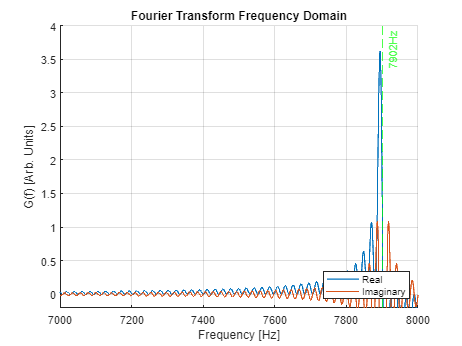


fplot(real(G(f)))
hold on
fplot(imag(G(f)))
xlim([7000 8000])
ylim([-0.2 4])
hold off
xline(21,'--g',{'21Hz'})
xline(440,'--g',{'440Hz'})
xline(2637,'--g',{'2637Hz'})
xline(7902,'--g',{'7902Hz'})



%beautifying curve
title("Fourier Transform Frequency Domain")
xlabel("Frequency [Hz]")
ylabel("G(f) [Arb. Units]")
legend("Real","Imaginary","Location","southeast")

ax = gca;
ax.XAxisLocation = "bottom";
ax.YAxisLocation = "origin";
box off;
grid on;